# Funzione di trasferimento trasmissione elastica

## Parametri

Jm=2e-2;
Jc=4e-2;

k=1000;
h=.2;
hm=.01;

## Modello a 4 stati

Modello del 4° ordine con i seguenti stati: $x=\left\lbrack \theta_m ,\theta_c ,\omega_m ,\omega_c \right\rbrack$

A=[0 0 1 0;
   0 0 0 1;
   -k/Jm k/Jm -h/Jm-hm/Jm h/Jm;
   k/Jc -k/Jc h/Jc -h/Jc];
B=[0 0 ;
   0 0;
   1/Jm 0;
   0 1/Jc];
C=eye(4);
D=zeros(4,2);

model=ss(A,B,C,D);

## Conversione nella forma della funzione di trasferimento

sys_tf = tf(model);

% Motore
tf1 = minreal(zpk(sys_tf(3,1)))

tf1 =
 
        50 (s^2 + 5s + 2.5e04)
  ----------------------------------
  (s+0.1667) (s^2 + 15.33s + 7.5e04)
 
Continuous-time zero/pole/gain model.



% Carico
tf2 = minreal(zpk(sys_tf(4,1)))

tf2 =
 
             250 (s+5000)
  ----------------------------------
  (s+0.1667) (s^2 + 15.33s + 7.5e04)
 
Continuous-time zero/pole/gain model.



## Grafico dei modelli

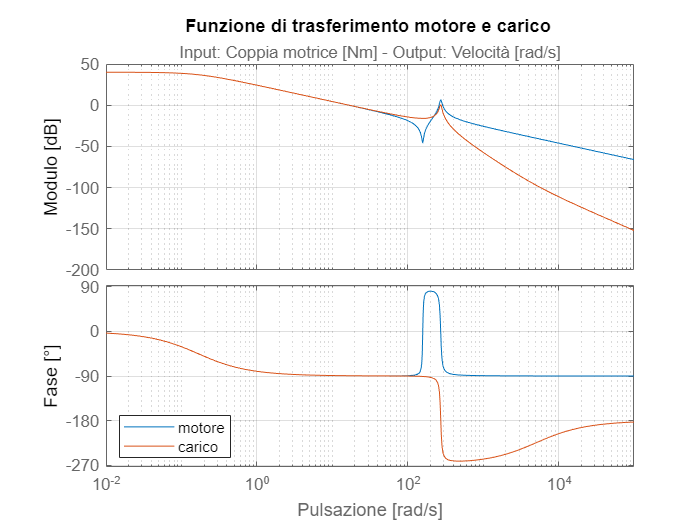

figure
tf1.OutputName = 'velocità'; tf1.InputName = 'coppia motrice';
bode(tf1)
hold on
bode(tf2)
title('Funzione di trasferimento motore e carico')
legend('motore','carico','Location','southwest')

% Titolo ed etichette assi personalizzate
axes=findall(gcf,'type','axes');    % (1): plot globale, (2): plot fase, (3): plot modulo
ha = get(axes(3),'title'); ha.String = 'Input: Coppia motrice [Nm] - Output: Velocità [rad/s]';
ha = get(axes(1),'title'); ha.String = 'Funzione di trasferimento motore e carico';

h_magnitude=get(axes(3),'YLabel'); set(h_magnitude,'String','Modulo [dB]')
h_phase=get(axes(2),'YLabel'); set(h_phase,'String','Fase [°]')
x_label=get(axes(2),'XLabel'); set(x_label,'String','Pulsazione [rad/s]')
x_label=get(axes(1),'XLabel'); set(x_label,'String','') % rimuove stringa di default

% Salvataggio della figura
set(gcf,'renderer','painters')
exportgraphics(gcf,'.\presentation\identification\motore_carico_trasmElastica.emf')